addpath(genpath('../helperFunctions'))

stimPath = '../stimulusSets/isettreeshrew/treeshrew_10/';
taskType = 'Camel_background_matrix';
stimSet = [taskType,'_quad/original/merged/'];

d = natsortfiles(dir('./behaviorData/shrewData.mat'));
load([d(end).folder,'/',d(end).name])

wave = 5:10:75;
orient = 0:15:165;
g = gabor(wave,orient);

targ_idx = unique(allData.(taskType).T_Expt_ID);
dist_idx = unique(allData.(taskType).D_Expt_ID);

allImgs = natsortfiles(dir([stimPath,stimSet]));
allImgs = allImgs(3:end);

tic
avgPwr_targ = nan(length(targ_idx),length(wave)*length(orient));
for tt = 1:length(targ_idx)
    img = double(imread(sprintf('%s%s/target_%d.png',stimPath,stimSet,targ_idx(tt))));
    img = mean(img,3);

    outMag = imgaborfilt(img,g);
    avgPwr_targ(tt,:) = mean(outMag,[1,2]);
    pwr_targ(tt,:) = outMag(:);
end

avgPwr_dist = nan(length(dist_idx),length(wave)*length(orient));
for dd = 1:length(dist_idx)
    img = double(imread(sprintf('%s%s/distractor_%d.png',stimPath,stimSet,dist_idx(dd))));
    img = mean(img,3);

    outMag = imgaborfilt(img,g);
    avgPwr_dist(dd,:) = mean(outMag,[1,2]);
    pwr_dist(dd,:) = outMag(:);
end
toc

Elapsed time is 683.329391 seconds.


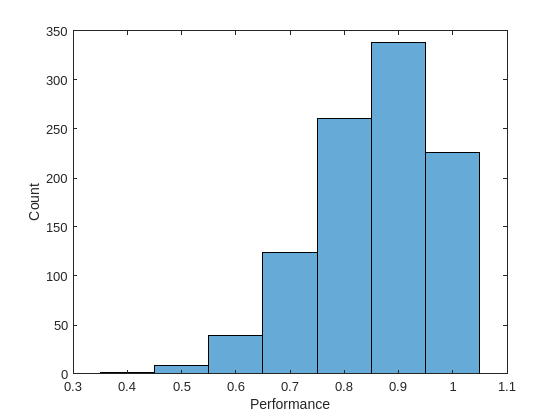

perf = nan(1,1000);
for i = 1:1000
    hpartition = cvpartition(length(targ_idx),'HoldOut',0.3);
    train_targ_idx = training(hpartition);
    test_targ_idx = test(hpartition);

    hpartition = cvpartition(length(dist_idx),'HoldOut',0.3);
    train_dist_idx = training(hpartition);
    test_dist_idx = test(hpartition);
    
    trainPwr_raw = [avgPwr_targ(train_targ_idx,:);avgPwr_dist(train_dist_idx,:)];
    testPwr_raw = [avgPwr_targ(test_targ_idx,:);avgPwr_dist(test_dist_idx,:)];
    
    mu = mean(trainPwr_raw);
    sd = std(trainPwr_raw);
    sd(sd == 0) = 1;
    
    trainX = (trainPwr_raw - mu) ./ sd;
    testX  = (testPwr_raw  - mu) ./ sd;
    
    trainY = [zeros(sum(train_targ_idx),1); ones(sum(train_dist_idx),1)];
    testY = [zeros(sum(test_targ_idx),1); ones(sum(test_dist_idx),1)];
    
    Mdl = fitcsvm(trainX, trainY);
    pred_train = predict(Mdl,trainX);
    pred = predict(Mdl, testX);
    perf(i) = sum((testY-pred)==0)/length(pred);
end

figure();
histogram(perf,[0.35:0.1:1.5])
xlim([0.3, 1.1])
xlabel('Performance')
ylabel('Count')